## 1. 构建符合要求的向量、矩阵或数组

- 一个包含 25 到 75 之间所有偶数的向量

v=26:2:74

v =     26    28    30    32    34    36    38    40    42    44    46    48    50    52    54    56    58    60    62    64    66    68    70    72    74


- 将上一题中构造出的向量中能被3整除的元素替为 0

for k=1:25
    if mod(v(k),3)==0
        v(k)=0;
    end
end
v

v =     26    28     0    32    34     0    38    40     0    44    46     0    50    52     0    56    58     0    62    64     0    68    70     0    74


## 2. 矩阵或数组的操作和计算

- 取出 A = magic(10) 矩阵中所有小于 50 的数，并将 A 中大于 50 数替换为 50

A=magic(10)

A =     92    99     1     8    15    67    74    51    58    40
    98    80     7    14    16    73    55    57    64    41
     4    81    88    20    22    54    56    63    70    47
    85    87    19    21     3    60    62    69    71    28
    86    93    25     2     9    61    68    75    52    34
    17    24    76    83    90    42    49    26    33    65
    23     5    82    89    91    48    30    32    39    66
    79     6    13    95    97    29    31    38    45    72
    10    12    94    96    78    35    37    44    46    53
    11    18   100    77    84    36    43    50    27    59


for k=1:10
    for l=1:10
        if A(k,l)<50
            B(k,l)=A(k,l);
        else
            A(k,l)=50;
        end
    end
end
A

A =     50    50     1     8    15    50    50    50    50    40
    50    50     7    14    16    50    50    50    50    41
     4    50    50    20    22    50    50    50    50    47
    50    50    19    21     3    50    50    50    50    28
    50    50    25     2     9    50    50    50    50    34
    17    24    50    50    50    42    49    26    33    50
    23     5    50    50    50    48    30    32    39    50
    50     6    13    50    50    29    31    38    45    50
    10    12    50    50    50    35    37    44    46    50
    11    18    50    50    50    36    43    50    27    50


B

B =      0     0     1     8    15     0     0     0     0    40
     0     0     7    14    16     0     0     0     0    41
     4     0     0    20    22     0     0     0     0    47
     0     0    19    21     3     0     0     0     0    28
     0     0    25     2     9     0     0     0     0    34
    17    24     0     0     0    42    49    26    33     0
    23     5     0     0     0    48    30    32    39     0
     0     6    13     0     0    29    31    38    45     0
    10    12     0     0     0    35    37    44    46     0
    11    18     0     0     0    36    43     0    27     0


## 3. 绘图

- 在同一张图中绘制４个子图，4 个子图分别为$y=\mathrm{sin}\;x$, $y=\mathrm{cos}\;x$, $y=x^2 +1$, $y=-5$

- 绘制以下椭圆函数


$$\frac{(x-1)^2}{16}+\frac{y^2}{4}=1$$



$$\frac{x-1}{4}=\mathrm{sin}\left(t\right),\frac{y}{2}=\mathrm{cos}\left(t\right)$$


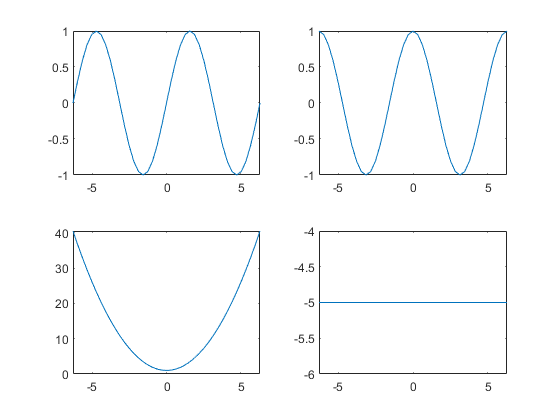

x=-2*pi:0.1*pi:2*pi;
subplot(2,2,1); plot(x,sin(x));
subplot(2,2,2); plot(x,cos(x));
subplot(2,2,3); plot(x,x.^2+1);
subplot(2,2,4); plot(x,0*x-5);

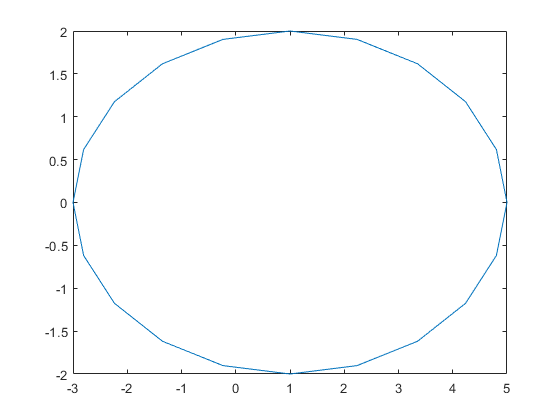

figure
t=-2*pi:0.1*pi:2*pi;
x=4*sin(t)+1;   y=2*cos(t);
plot(x,y);